## Run force matching tasks with MU pool models

This code sets up two sets of MU pool models, representing TA and SF, and uses existing neural drive mapping parameters to generate muscle forces matching desired force and FVL profiles

© 2024 Tiina Murtola/RVC

muscles = {'TA', 'SF'};

% names of parameter files; to re-optimise, run
% optimise_neural_drive_parameters.mlx and change file names to match here
paramFiles = {['optim_params_' muscles{1} '_precomp.mat'];...
    ['optim_params_' muscles{2} '_precomp.mat']};

Errs = struct;      % strcuture for errors
Fmatch = struct;   % structure for muscle forces


for m = 1:length(muscles)

    muscle = muscles{m};

    % generate tasks elements matching muscle
    switch muscle
        case 'TA'
            [elemTasks, dt, normFlag] = force_matching_tasks('trapezoidal');
        case 'SF'
            [elemTasks, dt, normFlag] = force_matching_tasks('simulated_reach');
    end

    % generate MU pools (mups)
    [npools, mups, Fmax] = muscle_MU_settings(muscle, dt);

    % scale tasks
    taskTargets = elemTasks;
    ntasks = size(taskTargets,1);
    if normFlag && strcmp(muscle,'TA') % scale trapezoidal task forces
        taskTargets(1,:,1) = Fmax*0.3*elemTasks(1,:,1);
        taskTargets(2,:,1) = Fmax*0.5*elemTasks(2,:,1);
    end

    % load neural drive parameters
    Pset = load(paramFiles{m},'paramsFf','paramsFb');
    nx = 2;     % number of multiplier parameters
    ny = nx-1;  % number of power parameters

    Errs.(muscle).erms = nan(ntasks,npools);
    Errs.(muscle).emax = nan(ntasks,npools);
    Errs.(muscle).etot = nan(ntasks,npools);
    Errs.(muscle).ermsFb = nan(ntasks,npools);
    Errs.(muscle).emaxFb = nan(ntasks,npools);
    Errs.(muscle).etotFb = nan(ntasks,npools);

    Fmatch.(muscle).target = taskTargets(:,:,1);
    Fmatch.(muscle).muscle = nan(ntasks,length(taskTargets),npools);
    Fmatch.(muscle).muscleFb = nan(ntasks,length(taskTargets),npools);

    for l = 1:ntasks

        forceTarget = taskTargets(l,:,1);
        fvl = taskTargets(l,:,2);

        driveSignals = [ones(size(forceTarget)); forceTarget./fvl];

        for k = 1:npools
            aff = Pset.paramsFf(1:nx,k);
            bff = Pset.paramsFf(nx+1:nx+ny,k);
            tauff = Pset.paramsFf(nx+ny+1,k);

            drive = zeros(size(forceTarget));
            drive(1:end-tauff) = aff'*driveSignals(:,tauff+1:end).^[1;bff];
            drive(end-tauff+1:end) = drive(end-tauff);

            activationPool = drive2activation(mups(k),drive);
            forceTotal = sum(activationPool.*mups(k).opts.max_force).*fvl;

            errorForce = 0;
            augDrive = zeros(size(drive));
            forceTotalFb = zeros(size(drive));

            mups(k) = reset(mups(k));

            for itime = 1:length(drive)

                augDrive(itime) = drive(itime) - Pset.paramsFb(k)*errorForce;

                [activationStep,mups(k)] = drive2activationStep(mups(k),augDrive(itime));
                forceTotalFb(itime) = sum(activationStep.*mups(k).opts.max_force).*fvl(itime);

                errorForce = forceTotalFb(itime)-forceTarget(itime);
            end

            Errs.(muscle).erms(l,k) = norm(forceTarget-forceTotal)./sqrt(length(forceTotal));
            Errs.(muscle).emax(l,k) = max(abs(forceTarget-forceTotal))/max(forceTarget);
            Errs.(muscle).etot(l,k) = abs(sum(forceTotal-forceTarget)*dt);
            Errs.(muscle).ermsFb(l,k) = norm(forceTarget-forceTotalFb)./sqrt(length(forceTotalFb));
            Errs.(muscle).emaxFb(l,k) = max(abs(forceTarget-forceTotalFb))/max(forceTarget);
            Errs.(muscle).etotFb(l,k) = abs(sum(forceTotalFb-forceTarget)*dt);

            Fmatch.(muscle).muscle(l,:,k) = forceTotal;
            Fmatch.(muscle).muscleFb(l,:,k) = forceTotalFb;

        end
    end

end

Plot errors

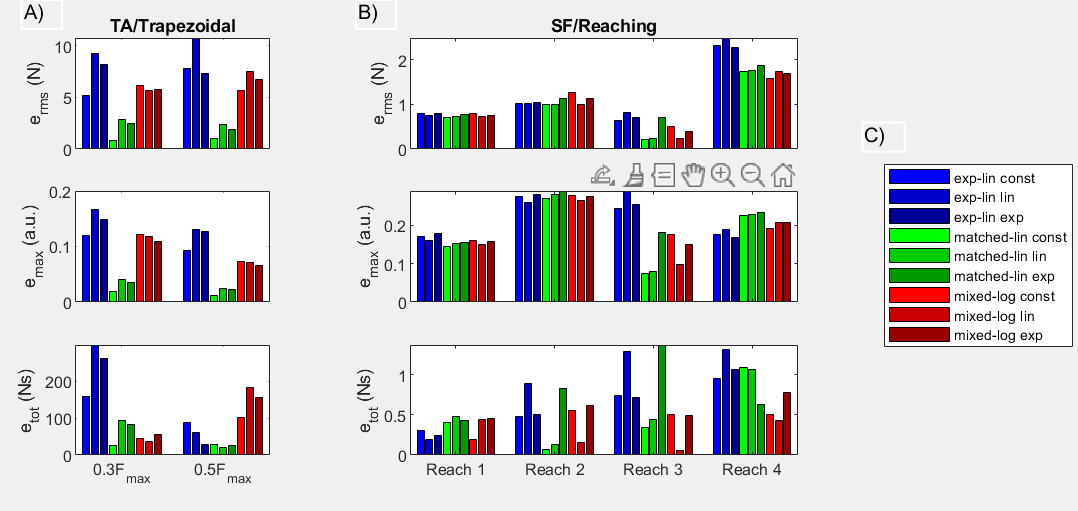

figure
set(gcf,'Visible','on')
set(gcf,'Units','centimeters')
set(gcf,'Position',[5 5 19 9])

pool_names ={'exp-lin const','exp-lin lin','exp-lin exp','matched-lin const','matched-lin lin','matched-lin exp','mixed-log const','mixed-log lin','mixed-log exp'};

ax1 = subplot(3,2,1);
ax1.Position(1) = 0.07;
ax1.Position(3) = 0.18;
bar(Errs.TA.erms)
ylabel('e_{rms} (N)')
title('TA/Trapezoidal')
set(gca,'XTickLabel','')

ax3 = subplot(3,2,3);
ax3.Position(1) = 0.07;
ax3.Position(3) = 0.18;
bar(Errs.TA.emax)
ylabel('e_{max} (a.u.)')
set(gca,'XTickLabel','')

ax5 = subplot(3,2,5);
ax5.Position(1) = 0.07;
ax5.Position(3) = 0.18;
bar(Errs.TA.etot)
ylabel('e_{tot} (Ns)')
set(gca,'XTick',1:2)
set(gca,'XTickLabel',{'0.3F_{max}','0.5F_{max}'})

ax2 = subplot(3,2,2);
ax2.Position(1) = 0.38;
ax2.Position(3) = 0.36;
bar(Errs.SF.erms)
ylabel('e_{rms} (N)')
title('SF/Reaching')
set(gca,'XTickLabel','')

ax4 = subplot(3,2,4);
ax4.Position(1) = 0.38;
ax4.Position(3) = 0.36;
bar(Errs.SF.emax)
ylabel('e_{max} (a.u.)')
set(gca,'XTickLabel','')
leg = legend(pool_names);
leg.Position(1:2) = [0.82 0.32];


ax6 = subplot(3,2,6);
ax6.Position(1) = 0.38;
ax6.Position(3) = 0.36;
bar(Errs.SF.etot)
ylabel('e_{tot} (Ns)')
set(gca,'XTick',1:4)
set(gca,'XTickLabel',{'Reach 1','Reach 2','Reach 3','Reach 4'})

newcolors=[0 0 1; 0 0 .8; 0 0 0.6; 0 1 0; 0 .8 0; 0 .6 0; 1 0 0; .8 0 0; .6 0 0];
colororder(newcolors)


A = annotation('textbox',[0.02 0.9 0.1 0.1],'string','A)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);
B = annotation('textbox',[0.33 0.9 0.1 0.1],'string','B)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);
C = annotation('textbox',[0.8 0.66 0.1 0.1],'string','C)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);

Plot feedforward time signals

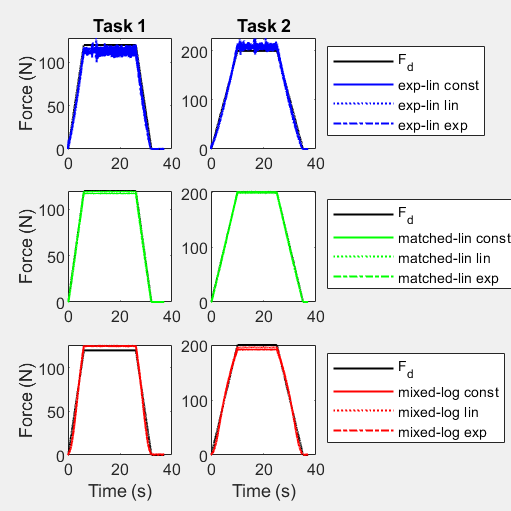

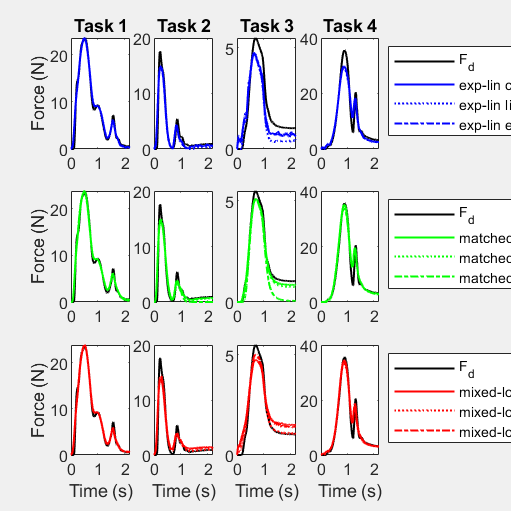

linespec = {'k-','b-','b:','b-.','g-','g:','g-.','r-','r:','r-.'};

for m = 1:length(muscles)
    muscle = muscles{m};
    ntasks = size(Fmatch.(muscle).target,1);

    figure
    set(gcf,'Units','centimeters')
    set(gcf,'Visible','on')

    for l = 1:ntasks
        
        forceTarget = Fmatch.(muscle).target(l,:,1);
        time = (0:length(forceTarget)-1)*dt;

        % plot target forces (nb. extra column for legends)
        subplot(3,ntasks+1,l)
        plot(time,forceTarget,linespec{1})
        hold on
        subplot(3,ntasks+1,ntasks+1+l)
        plot(time,forceTarget,linespec{1})
        hold on
        subplot(3,ntasks+1,2*ntasks+2+l)
        plot(time,forceTarget,linespec{1})
        hold on
        
        % plot muscle forces, grouped by threshold scheme
        for k = 1:npools
            subplot(3,ntasks+1,floor((k-1)/3)*(ntasks+1)+l)
            hold on
            plot(time,Fmatch.(muscle).muscle(l,:,k),linespec{k+1})

        end
    end
    
    % add labels & legends
    for axi = 1:ntasks
        subplot(3,ntasks+1,axi)
        title(['Task ' num2str(axi)])
    end
    for axi = 1:(ntasks+1):3*(ntasks+1)
        subplot(3,ntasks+1,axi)
        ylabel('Force (N)')
    end
    for axi = 2*(ntasks+1)+1:3*(ntasks+1)-1
        subplot(3,ntasks+1,axi)
        xlabel('Time (s)')
    end
    for ind = 1:3
        axi = ntasks+(ind-1)*(ntasks+1);
        subplot(3,ntasks+1,axi)
        l1 = legend({'F_d',pool_names{(ind-1)*3+1:ind*3}});
        switch muscle
            case 'TA'
                l1.Position(1) = 0.64;
            case 'SF'
                l1.Position(1) = 0.76;
        end
    end    

end

Plot stacked errors for feedforward vs feedback

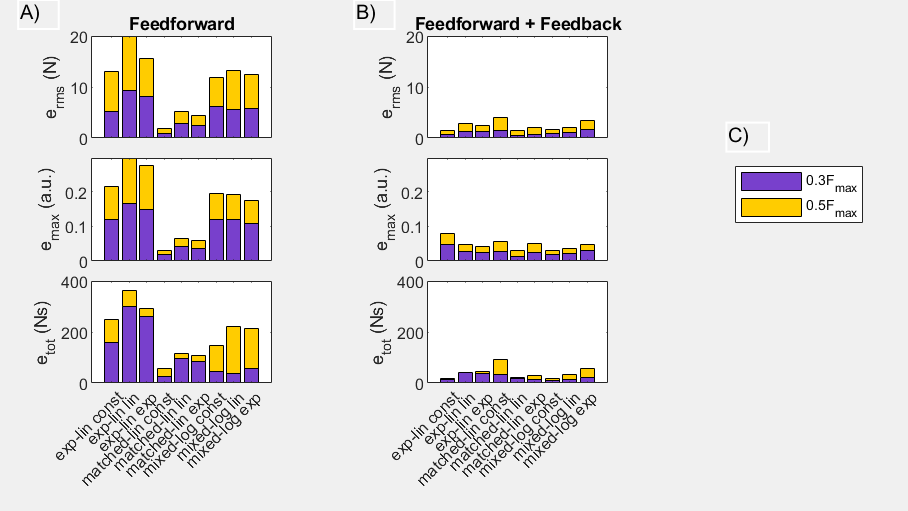

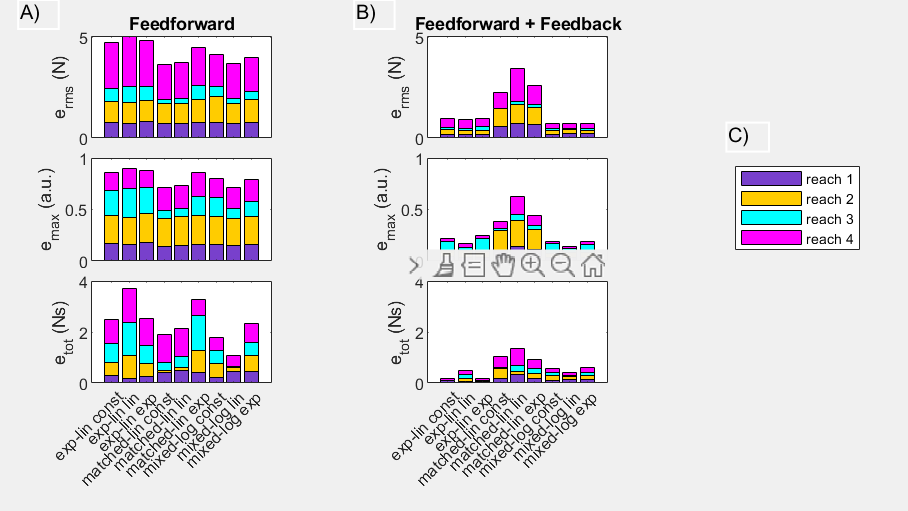

for m = 1:length(muscles)
    figure
    set(gcf,'Visible','on')
    set(gcf,'Units','centimeters')
    set(gcf,'Position',[5 5 16 9])
    subplot(3,2,1)
    set(gca,'Position',[.10 .73 .20 .20])
    bar(Errs.(muscles{m}).erms','stacked')
    set(gca,'XTickLabel','')
    ylabel('e_{rms} (N)')
    yl = ylim;
    title('Feedforward')
    subplot(3,2,2)
    set(gca,'Position',[.47 .73 .20 .20])
    bar(Errs.(muscles{m}).ermsFb','stacked')
    set(gca,'XTickLabel','')
    ylim(yl);
    ylabel('e_{rms} (N)')
    title('Feedforward + Feedback')

    
    subplot(3,2,3)
    set(gca,'Position',[.10 .49 .20 .20])
    bar(Errs.(muscles{m}).emax','stacked')
    set(gca,'XTickLabel','')
    yl = ylim;
    ylabel('e_{max} (a.u.)')
    %title('Feedforward')
    subplot(3,2,4)
    set(gca,'Position',[.47 .49 .20 .20])
    bar(Errs.(muscles{m}).emaxFb','stacked')
    set(gca,'XTickLabel','')
    ylim(yl);
    ylabel('e_{max} (a.u.)')
    %title('Feedforward + Feedback')
    if m== 1
        l1 = legend('0.3F_{max}','0.5F_{max}');
        l1.Position(1) = 0.81;
    else
        l2 = legend('reach 1','reach 2','reach 3','reach 4');
        l2.Position(1) = 0.81;
    end

    subplot(3,2,5)
    set(gca,'Position',[.10 .25 .20 .20])
    bar(Errs.(muscles{m}).etot','stacked')
    set(gca,'XTickLabel',pool_names)
    set(gca,'XTickLabelRotation',45)
    yl = ylim;
    ylabel('e_{tot} (Ns)')
    %title('Feedforward')
    subplot(3,2,6)
    set(gca,'Position',[.47 .25 .20 .20])
    bar(Errs.(muscles{m}).etotFb','stacked')
    set(gca,'XTickLabel',pool_names)
    set(gca,'XTickLabelRotation',45)
    ylim(yl);
     ylabel('e_{tot} (Ns)')
   

    newcolors=[0.47 0.25 0.80; 1 0.80 0; 0 1 1; 1 0 1;  ];
    colororder(newcolors)

    A = annotation('textbox',[0.02 0.9 0.1 0.1],'string','A)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);
    B = annotation('textbox',[0.39 0.9 0.1 0.1],'string','B)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);
    C = annotation('textbox',[0.8 0.66 0.1 0.1],'string','C)','FitBoxToText','on','Margin',1,'EdgeColor',[ 1 1 1]);
    
   
end